## CST ELEMENT *(it’s more easy than quad)*

*Prof. J. Morlier October 2020*

Correction of example given in the course. CST element  analytics

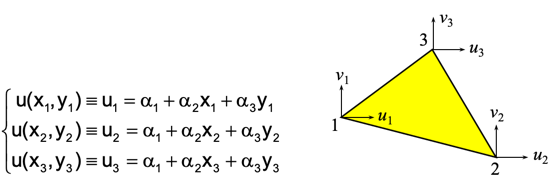

clear all; close all;
syms alpha_1 alpha_2 alpha_3 real
syms x_1 x_2 x_3 real
syms y_1 y_2 y_3 real

model=[1 1 1; x_1 x_2 x_3; y_1 y_2 y_3]'

$$model = \left(\begin{array}{ccc} 1 & x_{1} & y_{1}\\ 1 & x_{2} & y_{2}\\ 1 & x_{3} & y_{3} \end{array}\right)$$

check determinant

A = det(model)/2;
sigma_1=2*A

$$sigma\_1 = x_{1}\,y_{2}-x_{2}\,y_{1}-x_{1}\,y_{3}+x_{3}\,y_{1}+x_{2}\,y_{3}-x_{3}\,y_{2}$$


invmodel=(inv(model))

$$invmodel = \begin{array}{l} \left(\begin{array}{ccc} \frac{x_{2}\,y_{3}-x_{3}\,y_{2}}{\sigma_{1}} & -\frac{x_{1}\,y_{3}-x_{3}\,y_{1}}{\sigma_{1}} & \frac{x_{1}\,y_{2}-x_{2}\,y_{1}}{\sigma_{1}}\\ \frac{y_{2}-y_{3}}{\sigma_{1}} & -\frac{y_{1}-y_{3}}{\sigma_{1}} & \frac{y_{1}-y_{2}}{\sigma_{1}}\\ -\frac{x_{2}-x_{3}}{\sigma_{1}} & \frac{x_{1}-x_{3}}{\sigma_{1}} & -\frac{x_{1}-x_{2}}{\sigma_{1}} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=x_{1}\,y_{2}-x_{2}\,y_{1}-x_{1}\,y_{3}+x_{3}\,y_{1}+x_{2}\,y_{3}-x_{3}\,y_{2} \end{array}$$

check only f_1 

syms f_1 real
f1=x_2*y_3-x_3*y_2

$$f1 = x_{2}\,y_{3}-x_{3}\,y_{2}$$

subs(invmodel,x_2*y_3-x_3*y_2,f_1)

$$ans = \begin{array}{l} \left(\begin{array}{ccc} \frac{f_{1}}{\sigma_{1}} & -\frac{x_{1}\,y_{3}-x_{3}\,y_{1}}{\sigma_{1}} & \frac{x_{1}\,y_{2}-x_{2}\,y_{1}}{\sigma_{1}}\\ \frac{y_{2}-y_{3}}{\sigma_{1}} & -\frac{y_{1}-y_{3}}{\sigma_{1}} & \frac{y_{1}-y_{2}}{\sigma_{1}}\\ -\frac{x_{2}-x_{3}}{\sigma_{1}} & \frac{x_{1}-x_{3}}{\sigma_{1}} & -\frac{x_{1}-x_{2}}{\sigma_{1}} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=f_{1}+x_{1}\,y_{2}-x_{2}\,y_{1}-x_{1}\,y_{3}+x_{3}\,y_{1} \end{array}$$

Given nodal displacements 

{u1, v1, u2, v2, u3, v3, u4, v4} = {−0.1, **0**, 0.1,**0**, −0.1,**0**, 0.1,**0**}

•Element 1: Nodes 1-2-4

•Given, xi,yi, ui,vi, find Ni(x,y) then COMPUTE STRAIN!

Calculate the shape function of Node 1 in the top element. 

{u1, v1, u2, v2, u3, v3, u4, v4} = {−0.1, **0**, 0.1,**0**, −0.1, **0**, 0.1,**0**}

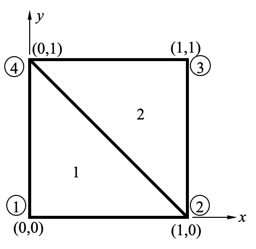

q=[-0.1,0,0.1,0,-0.1,0,0.1,0]'

q =    -0.1000
         0
    0.1000
         0
   -0.1000
         0
    0.1000
         0


for element 1, node 1, 2 and 4

ud=q([1 3 7]);

syms u_1 u_2 u_3 real
u=[u_1 u_2 u_3]'

$$u = \left(\begin{array}{c} u_{1}\\ u_{2}\\ u_{3} \end{array}\right)$$

alpha_1=invmodel(1,:)*u;
alpha_2=invmodel(2,:)*u;
alpha_3=invmodel(3,:)*u;
% 
alpha=[alpha_1 alpha_2 alpha_3];
alpha=subs(alpha, [x_1 x_2 x_3 y_1 y_2 y_3 u_1 u_2 u_3], [0 1 0 0 0 1 q(1) q(3) q(7)])

$$alpha = \left(\begin{array}{ccc} -\frac{1}{10} & \frac{1}{5} & \frac{1}{5} \end{array}\right)$$

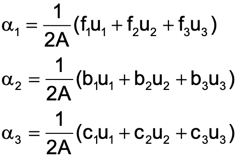

% 
syms x y real
N1=invmodel(:,1)'*[1 x y]';
N2=invmodel(:,2)'*[1 x y]';
N3=invmodel(:,3)'*[1 x y]';

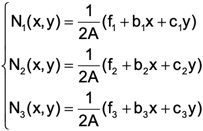

N=[N1;N2;N3];
N=subs(N, [x_1 x_2 x_3 y_1 y_2 y_3 ], [0 1 0 0 0 1])% 

$$N = \left(\begin{array}{c} 1-y-x\\ x\\ y \end{array}\right)$$

u=N'*ud

$$u = \frac{x}{5}+\frac{y}{5}-\frac{1}{10}$$


vd=q([2 4 6]);
v=N'*vd

$$v = 0$$